**OPTIMALNA METODA**

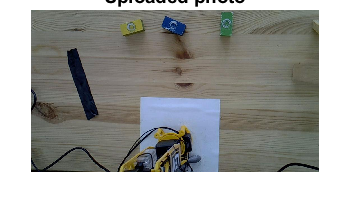


img = imread('slika_projekt.jpg');
imshow(img); title('Uploaded photo');

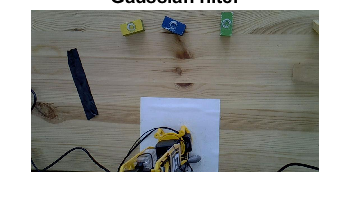



gauss_filt = fspecial('gaussian', [1,1], 5);
img_filt= imfilter(img, gauss_filt);
figure;
imshow(img_filt); title('Gaussian filter');

imwrite(img,'proba7.jpg')

%% 
img_hsv = rgb2hsv(img_filt);
img_gray = rgb2gray(img_filt);
I = img_hsv;

**Crna**

black= 1

black = 1

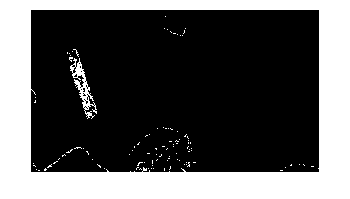

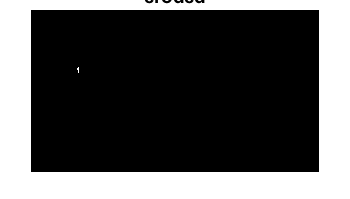

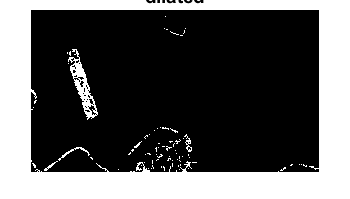

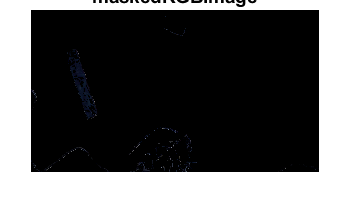

s = 153×1 struct array with fields:
    BoundingBox


center = 153×1 struct array with fields:
    Centroid


center_1_x = 2.7750

center_1_y = 537.0250

center_2_x = 65.7750

center_2_y = 537.0250

center_3_x = -61.7250

center_3_y = 537.0250

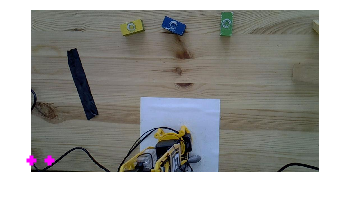

%%sa segmentacijom kad je nagnuto, ostalo moze bez
switch black
    case 0
        I = img_filt;

        angle = 0
        
        black = imread('slika_projekt.jpg');
        black_rotated = imrotate(black, angle);
        black_location = find_object_black(I,black_rotated);
        x1_black = black_location(1)
        y1_black = black_location(2)
        x2_black = black_location(3)
        y2_black = black_location(4)
        x3_black = black_location(5)
        y3_black = black_location(6)

    case 1
        % Define thresholds for channel 1 based on histogram settings
        channel1Min = 0.59;
        channel1Max =0.8;
        
        % Define thresholds for channel 2 based on histogram settings
        channel2Min =0;
        channel2Max =0.78;
        
        % Define thresholds for channel 3 based on histogram settings
        channel3Min =0.022;
        channel3Max =0.194;

        sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
            (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
            (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
        BW = sliderBW;
        imshow(BW);
        figure;
        
        se = strel('square', 10);
        eroded = imerode(BW, se);
        imshow(eroded);title('eroded');
        figure;
        se = strel('square', 2);
        dilated = imdilate(BW, se);
        imshow(dilated);title('dilated')
        figure;
        
        %%----------ako eroded/dilated pomaze---------
        BW= dilated;
        %---------------------------------------------
                
        % Initialize output masked image based on input image.
        maskedRGBImage = img_filt;
                
        % Set background pixels where BW is false to zero.
        maskedRGBImage(repmat(~BW,[1 1 3])) = 0;
                
                
        figure();imshow(maskedRGBImage);title('maskedRGBImage');
        figure();imshow(BW);title('BW');
        
        bw_x = im2bw(BW);
        bw_x = imfill(BW,'holes');
        [bwLabel, num]= bwlabel(bw_x);
        
        s=regionprops(bwLabel,'BoundingBox')
        
        center=regionprops(bwLabel,'Centroid')
        imshow(BW);
        hold on
        %---ENTER WICH CENTROID------
        i =3;
        j = 3;
        %----------------------------
        rectangle('Position',s(i).BoundingBox,'Edgecolor', 'magenta')
        hold on
        plot(center(j).Centroid(1),center(j).Centroid(2), 'm+', 'MarkerSize', 5, 'LineWidth', 2);
        title("Center of the mass BW")
        hold off
        
        imshow(maskedRGBImage)
        hold on
        rectangle('Position',s(i).BoundingBox,'Edgecolor', 'magenta')
        hold on
        plot(center(j).Centroid(1),center(j).Centroid(2), 'm+', 'MarkerSize', 5, 'LineWidth', 2);
        title("Center of the mass maskedRGBImage")
        hold off
        
        imshow(img)
        hold on
        plot(center(j).Centroid(1),center(j).Centroid(2), 'm+', 'MarkerSize', 5, 'LineWidth', 2);
        title("Center in image - metoda1")
        hold off
        
        center_1_x = center(j).Centroid(1)
        center_1_y = center(j).Centroid(2)
        %%optimalno 56.5
        center_2_x = center(j).Centroid(1)+ 63
        center_2_y = center(j).Centroid(2)- 0
        %%optimalno 56.5
        center_3_x = center(j).Centroid(1)- 64.5
        center_3_y = center(j).Centroid(2)+ 0

     
    
        imshow(img);
        hold on
        plot(center_1_x,center_1_y, 'm+', 'MarkerSize', 5, 'LineWidth', 2);
        hold on
        plot(center_2_x,center_2_y, 'm+', 'MarkerSize', 5, 'LineWidth', 2);
        hold on
        plot(center_3_x,center_3_y, 'm+', 'MarkerSize', 5, 'LineWidth', 2);
        hold off

end

function location= find_object_black(I,T)
    I= rgb2gray(I);
    [Ir, Ic]=size(I);
    figure(1);
    imshow(I);
    T= rgb2gray(T);
    figure(2)
    imshow(T);
    [Tr, Tc]=size(T);
    R = normxcorr2(T,I);
    R = imcrop(R,[Tc Tr Ic Ir]);
    [r, c, v] = find(R==(max(max(R))))
    RGB = insertShape(I, "rectangle", [c r Tc Tr], "LineWidth", 3,"Color","magenta");
    figure(3)
    %optimalno 0.165
    center_1_x = c+Tc*0.1
    %optimalno 0.495
    center_1_y = r+Tr*0

    center_2_x = c+Tc*0.495
    center_2_y = r+Tr*0

    %optimalno 0.825
    center_3_x = c+Tc*0.2
    %optimalno 0.495
    center_3_y = r+Tr*0

    imshow(RGB);
    hold on
    plot(center_1_x,center_1_y, 'm+', 'MarkerSize', 5, 'LineWidth', 2);
    hold on
    plot(center_2_x,center_2_y, 'm+', 'MarkerSize', 5, 'LineWidth', 2);
    hold on
    plot(center_3_x,center_3_y, 'm+', 'MarkerSize', 5, 'LineWidth', 2);
    hold off
    location = [[center_1_x,center_1_y], [center_2_x,center_2_y], [center_3_x,center_3_y]];

end
